clear
clc

Omega_ = [.35,.5;.5,.75];
Sigma_ = eye(2);
df_F_1 = 10;
df_F_2 = 15;

param = [df_F_1(1); df_F_2(1); vech(chol(Sigma_,'lower')); vech(chol(Omega_,'lower'))]';

**Does mncFrnd work? **

- mean(data_mat,3) = Sigma_ + Omega/df_F_1 ?

T = 1e6;
data_mat = mncFrnd(ones(T,1)*df_F_1, ones(T,1)*df_F_2, repmat(Sigma_,1,1,T), repmat(Omega_,1,1,T));

data_mat_vech = vech_(data_mat)';
theo_mean = vech(Sigma_+Omega_/df_F_1)';
mean_dev_data_mat_vech = NaN(T,3);
parfor ii = 1:T
    mean_dev_data_mat_vech(ii,:) = mean(data_mat_vech(1:ii,:),1)-theo_mean;
end

Starting parallel pool (parpool) using the 'local' profile ...
connected to 4 workers.


It seems like there is a small numerical inaccuracy in mncFrnd, but nothing to be really concerned about.

mean_dev_data_mat_vech(end,:)

ans =    1.0e-03 *

    0.1855    0.3148   -0.6917


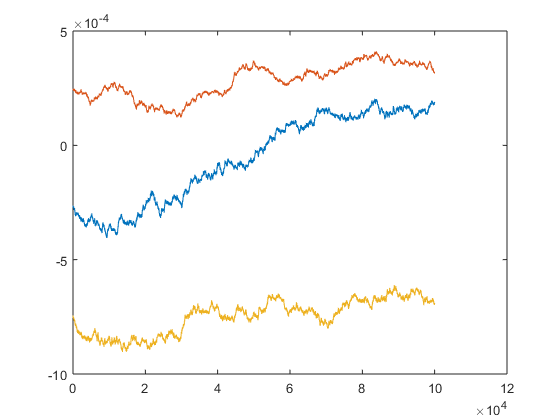

plot(mean_dev_data_mat_vech(end-1e5:end,:))

**Does mncFlike work?**

- **Liegt es daran, dass \Sigma^-1 \Omega richtig ist?**

- **Liegt es daran, dass Omega zu klein ist?**

- **Liegt es an einem Solver Issue, i.e. könnte ich Omega_*100 in die funktion reinstecken?**

- **Liegt es an einem Solver Issue, i.e. sollte man weit weg von der Nullmatrix starten für Omega_?**

- **Liegt es daran, dass Sigma_ nah an der Einheitsmatrix ist?**

- **Vielleicht kommt es auf das Größenverhältnis Omega_ zu Sigma_ an?**

**Hinweise:**

- **Sigma_ = eye(2)*1.01, Omega_ = [.35, .5, .5, .75] funktioniert nicht.**

**Was tue ich gerade?**

- **Ich probiere mehrere Sigma_ - Omega_ Konstellationen aus.**


clear
clc
Omega_ = randn(2);
Omega_ = Omega_*Omega_';
Sigma_ = eye(2);
df_F_1 = 10;
df_F_2 = 15;

param = [df_F_1(1); df_F_2(1); vech(chol(Sigma_,'lower')); vech(chol(Omega_,'lower'))]';

options = optimoptions('fmincon','Display','off','MaxFunEval',1e5);
eparam = NaN(4,8);
T = 1e3;
parfor ii = 1:4
    data_mat = mncFrnd(ones(T,1)*df_F_1, ones(T,1)*df_F_2, repmat(Sigma_,1,1,T), repmat(Omega_,1,1,T));

    fun_ = @(x) fun(x,data_mat);

    eparam(ii,:) = fmincon(fun_,[5,10,1,0,1,1,0,1],[],[],[],[],[3;3],[],[],options);
end

Starting parallel pool (parpool) using the 'local' profile ...
connected to 4 workers.
> In checkbounds (line 33)
> In checkbounds (line 33)
> In checkbounds (line 33)
> In checkbounds (line 33)
  In fmincon (line 308)
  In parallel_function>make_general_channel/channel_general (line 917)
  In remoteParallelFunction (line 41)
  In fmincon (line 308)
  In parallel_function>make_general_channel/channel_general (line 917)
  In remoteParallelFunction (line 41)
  In fmincon (line 308)
  In parallel_function>make_general_channel/channel_general (line 917)
  In remoteParallelFunction (line 41)
  In fmincon (line 308)
  In parallel_func


for ii = 1:4
    eSigma(:,:,ii) = ivech(eparam(ii,3:5),'lower')*ivech(eparam(ii,3:5),'lower')';
    eOmega(:,:,ii) = ivech(eparam(ii,6:8),'lower')*ivech(eparam(ii,6:8),'lower')';
    eEV(:,:,ii) = eSigma(:,:,ii) + eOmega(:,:,ii)/eparam(ii,1);
    InvSigmaOmega(:,:,ii) = eSigma(:,:,ii)\eOmega(:,:,ii);
end
Sigma_

Sigma_ =     0.6433   -0.5379
   -0.5379    1.3864


mean(eSigma,3)

ans =     0.6778   -0.5619
   -0.5619    1.3265


Omega_

Omega_ =     1.4741    1.3414
    1.3414    3.5888


mean(eOmega,3)

ans =     1.1529    1.4593
    1.4593    4.2495


Sigma_ + Omega_/df_F_1

ans =     0.7907   -0.4038
   -0.4038    1.7453


mean(eEV,3)

ans =     0.7977   -0.4144
   -0.4144    1.7618


Sigma_\Omega_

ans =     4.5896    6.2907
    2.7482    5.0292


mean(InvSigmaOmega,3)

ans =     5.0845    8.5443
    3.3883    7.0998


beep

function y = fun(x,data_mat)
if size(x,1) < size(x,2)
    x = x';
end    
T = size(data_mat,3);
df_F_1 = ones(T,1)*x(1);
df_F_2 = ones(T,1)*x(2);
Sigma_ = ivech(x(3:5),'lower');
Sigma_ = repmat(Sigma_*Sigma_',1,1,T);
Omega_ = ivech(x(6:8),'lower');
Omega_ = repmat(Omega_*Omega_',1,1,T);
y = mncFlike(data_mat, df_F_1, df_F_2, Sigma_, Omega_, 100);
end